% region dependencies
addpath('functions/dft/');
addpath('functions/util/');
addpath('functions/plotters/');
% endregion dependencies

% region constants
X_AXIS = 1;
Y_AXIS = 2;
Z_AXIS = 3;
DATASETS_DIR = 'resources/txt/datasets';
LABELS_PATH = 'resources/txt/labels.txt';
COLORS = {'#2f4f4f', '#7f0000', '#008000', '#00008b', '#ff8c00', '#CC3322', '#11ff00', '#00ffff', '#ff00ff', '#1e90ff', '#ffe4b5', '#fd4002'};
ACTIVITIES = ["WALK", "WALK\_UP", "WALK\_DOWN", "SIT", "STAND", "LAY", "STAND\_SIT", "SIT\_STAND", "SIT\_LIE", "LIE\_SIT", "STAND\_LIE", "LIE\_STAND"];
FS = 50;
THRESHOLD = 0.25;
WINDOW_SIZE = 6;
OVERLAP_SIZE = 3;
ACT_SIZES = [2000, 2500, 1500];
DYNAMIC_ACTIVITIES = [1, 2, 3];
% end region constants

labels = dlmread(LABELS_PATH, ' ');
datasets = load_datasets(DATASETS_DIR);

[num_act_ocurrences, meaned_acts_x, freqs_x, dfts_x] = prepare_datasets(datasets, X_AXIS, FS, ACT_SIZES, labels, ACTIVITIES);
[~, meaned_acts_y, freqs_y, dfts_y] = prepare_datasets(datasets, Y_AXIS, FS, ACT_SIZES, labels, ACTIVITIES);
[~, meaned_acts_z, freqs_z, dfts_z] = prepare_datasets(datasets, Z_AXIS, FS, ACT_SIZES, labels, ACTIVITIES);


grouped = group_activities(datasets, 1, labels, DYNAMIC_ACTIVITIES);
grouped{1}{1}

ans =     1.4208   -0.3403   -0.1250
    1.0028   -0.2042   -0.1083
    0.6833   -0.0611   -0.1083
    0.7333   -0.0833   -0.1208
    0.9569   -0.2639   -0.1375
    1.0500   -0.4028   -0.1444
    1.0139   -0.4153   -0.1042
    0.9500   -0.3931   -0.1056
    0.9500   -0.3597   -0.1028
    0.9528   -0.3153   -0.0861


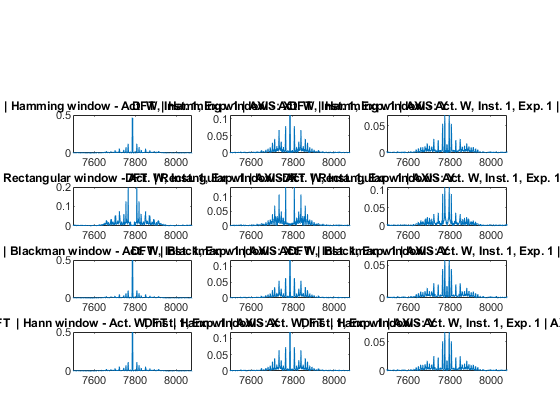


%plot_stft(cell2mat(datasets(7)), FS, @hamming, WINDOW_SIZE, OVERLAP_SIZE)

%plot_relevant_freqs(freqs_x, dfts_x, ACTIVITIES, THRESHOLD);
%plot_relevant_freqs(freqs_y, dfts_y, ACTIVITIES, THRESHOLD);
%plot_relevant_freqs(freqs_z, dfts_z, ACTIVITIES, THRESHOLD);

%plot_dataset_param(meaned_acts_x, ACTIVITIES, @get_abs_slope, 'Absolute slope comparison - Axis X', COLORS);
%plot_dataset_param(meaned_acts_y, ACTIVITIES, @get_abs_slope, 'Absolute slope comparison - Axis Y', COLORS);
%plot_dataset_param(meaned_acts_z, ACTIVITIES, @get_abs_slope, 'Absolute slope comparison - Axis Z', COLORS);

%plot_dataset_param(meaned_acts_x, ACTIVITIES, @get_max_dist, 'Max. dist. comparison - Axis X', COLORS);
%plot_dataset_param(meaned_acts_y, ACTIVITIES, @get_max_dist, 'Max. dist. slope comparison - Axis Y', COLORS);
%plot_dataset_param(meaned_acts_z, ACTIVITIES, @get_max_dist, 'Max. dist. slope comparison - Axis Z', COLORS);

%plot_meaned_activities(acts_x, X_AXIS, ACTIVITIES);
%plot_meaned_activities(acts_y, Y_AXIS, ACTIVITIES);
%plot_meaned_activities(acts_z, Z_AXIS, ACTIVITIES);
%plot_meaned_dfts(freqs_x, dfts_x, num_act_ocurrences, ACTIVITIES, X_AXIS);
%plot_meaned_dfts(freqs_y, dfts_y, num_act_ocurrences, ACTIVITIES, Y_AXIS);%
%plot_meaned_dfts(freqs_z, dfts_z, num_act_ocurrences, ACTIVITIES, Z_AXIS);

%plot_activity(datasets, FS, COLORS, labels, ACTIVITIES, 1, 13); % (..., exp, activity)
%plot_datasets(datasets, FS, labels, ACTIVITIES, COLORS);
%plot_dfts(datasets, fs, labels);
plot_windowed_dft(datasets{1}, FS, 7496:8078, @hamming, ' | Hamming window - Act. W, Inst. 1, Exp. 1', 1);
plot_windowed_dft(datasets{1}, FS, 7496:8078, @rectwin, ' | Rectangular window - Act. W, Inst. 1, Exp. 1', 2);
plot_windowed_dft(datasets{1}, FS, 7496:8078, @blackman, ' | Blackman window - Act. W, Inst. 1, Exp. 1', 3);
plot_windowed_dft(datasets{1}, FS, 7496:8078, @hann, ' | Hann window - Act. W, Inst. 1, Exp. 1', 4);